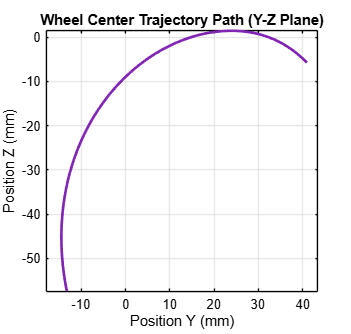

%รัน Multibody ก่อน เพื่อให้มีข้อมูล x,v,a wheel
t = out.x_wheel.Time;
idx = (t >= 0.02) & (t <= 4.38);
pos = get3(out.x_wheel, t);
vel = get3(out.v_wheel, t);
acc = get3(out.a_wheel, t);

fig1 = figure('Color', 'w', 'Position', [100, 420, 520, 495]);
if isprop(fig1, 'Theme'), fig1.Theme = 'light'; end
ax1 = axes('Parent', fig1);
plot(ax1, pos(:,2), pos(:,3), 'Color', [0.50 0.15 0.70], 'LineWidth', 2.0);
title(ax1, 'Wheel Center Trajectory Path (Y-Z Plane)', 'FontSize', 11, 'FontWeight', 'bold', 'Color', 'k');
xlabel(ax1, 'Position Y (mm)', 'FontSize', 10, 'Color', 'k');
ylabel(ax1, 'Position Z (mm)', 'FontSize', 10, 'Color', 'k');
grid(ax1, 'on'); axis(ax1, 'equal'); xlim(ax1, [-18 43.5]); ylim(ax1, [-57.5 1.5]);
set(ax1, 'FontSize', 10, 'Color', 'w', 'XColor', 'k', 'YColor', 'k', 'Box', 'on', 'GridColor', [0.85 0.85 0.85], 'GridAlpha', 0.6);
exportgraphics(fig1, 'Wheel_Trajectory.png', 'BackgroundColor', 'w', 'Resolution', 300);

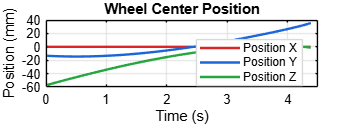

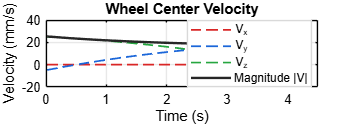

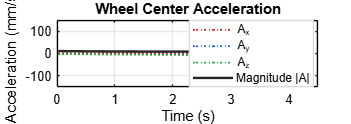


c = {[0.85 0.15 0.15], [0.10 0.40 0.85], [0.15 0.65 0.25], [0.15 0.15 0.15]};
cfg = {
    pos, {'-','-','-'}, [1.8 1.8 1.8], 'Wheel Center Position', 'Position (mm)', {'Position X','Position Y','Position Z'}, [-60 40], 'Wheel_Position.png', 640;
    [vel vecnorm(vel,2,2)], {'--','--','--','-'}, [1.3 1.3 1.3 1.8], 'Wheel Center Velocity', 'Velocity (mm/s)', {'V_x','V_y','V_z','Magnitude |V|'}, [-20 40], 'Wheel_Velocity.png', 330;
    [acc vecnorm(acc,2,2)], {':',':',':','-'}, [1.3 1.3 1.3 1.8], 'Wheel Center Acceleration', 'Acceleration (mm/s^2)', {'A_x','A_y','A_z','Magnitude |A|'}, [-150 150], 'Wheel_Acceleration.png', 20
    };

for k = 1:3
    fig = figure('Color', 'w', 'Position', [640, cfg{k,9}, 780, 275]);
    if isprop(fig, 'Theme'), fig.Theme = 'light'; end
    ax = axes('Parent', fig); hold(ax, 'on');
    D = cfg{k,1}; ls = cfg{k,2}; lw = cfg{k,3};
    for j = 1:size(D, 2)
        plot(ax, t(idx), D(idx,j), ls{j}, 'Color', c{j}, 'LineWidth', lw(j));
    end
    title(ax, cfg{k,4}, 'FontSize', 11, 'FontWeight', 'bold', 'Color', 'k');
    xlabel(ax, 'Time (s)', 'FontSize', 10, 'Color', 'k');
    ylabel(ax, cfg{k,5}, 'FontSize', 10, 'Color', 'k');
    lgd = legend(ax, cfg{k,6}, 'Location', 'best');
    set(lgd, 'Color', 'w', 'TextColor', 'k', 'EdgeColor', [0.85 0.85 0.85]);
    grid(ax, 'on'); xlim(ax, [0 4.5]); ylim(ax, cfg{k,7});
    set(ax, 'FontSize', 10, 'Color', 'w', 'XColor', 'k', 'YColor', 'k', 'Box', 'on', 'GridColor', [0.85 0.85 0.85], 'GridAlpha', 0.6);
    exportgraphics(fig, cfg{k,8}, 'BackgroundColor', 'w', 'Resolution', 300);
end


function M = get3(sig, t)
M = squeeze(sig.Data);
if size(M, 1) ~= numel(t), M = M.'; end
end